clear all;
clc;
close all;

XK = [6, -5 + 11i, 0, -5 - 11i];
CXK = conj(XK);

x=CXK;
p = nextpow2(length(x));
x = [x zeros(1, (2^p) - length(x))];
N = length(x);
S = log2(N);
Half = 1;
x = bitrevorder(x);
for stage = 1:S
    for index = 0:(2^stage):(N - 1)
        for n = 0:(Half - 1)
            pos = n + index + 1;
            pow = (2^(S - stage)) * n;
            w = exp((-1i) * (2 * pi) * pow / N);
            a = x(pos) + x(pos + Half) .* w;
            b = x(pos) - x(pos + Half) .* w;
            x(pos) = a;
            x(pos + Half) = b;
        end
    end
    Half = 2 * Half;
end

disp("Radix-2 DIT FFT method result")

Radix-2 DIT FFT method result


x = conj(x) ./ 4;
x

x =   -1.0000 + 0.0000i  -4.0000 + 0.0000i   4.0000 + 0.0000i   7.0000 - 0.0000i



Xvk=ifft(XK,N);
disp("Direct computation")

Direct computation


Xvk

Xvk =     -1    -4     4     7


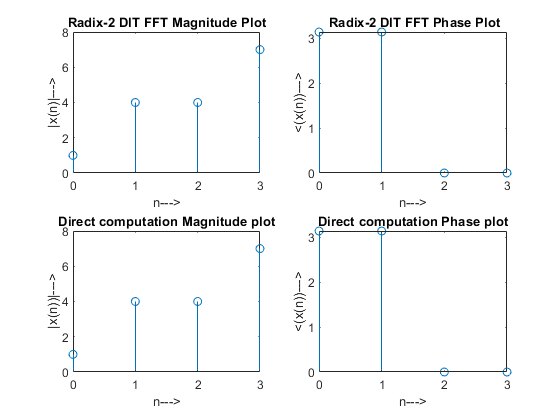


k = 0:N - 1;
subplot(2, 2, 1)
stem(k, abs(x))
xlabel('n--->')
ylabel('|x(n)|--->')
title('Radix-2 DIT FFT Magnitude Plot')

subplot(2, 2, 2)
stem(k, angle(x))
xlabel('n--->')
ylabel('<(x(n))--->')
title(' Radix-2 DIT FFT Phase Plot')

subplot(2, 2, 3)
stem(k, abs(Xvk))
xlabel('n--->')
ylabel('|x(n))|--->')
title('Direct computation Magnitude plot')

subplot(2, 2, 4)
stem(k, angle(Xvk))
xlabel('n--->')
ylabel('<(x(n))--->')
title('Direct computation Phase plot')